# Receiver Operating Characteristic (ROC)

As done in several of our previously published works, we always use ROC analysis to examine the performance of proposed analysis methods, focusing on the AUC as the outcome variable and comparing results based on varying “data quality” inputs. To generate ROC analysis, we will take the experimental data provided by our collaborating partners as well as our own datasets. For evoked signal analysis, a simulated evoked response was added to half of the channels of the experimental fNIRS data at specific contrast-to-noise ratio based on expectations of the study effect. Through numerous iterations of jittered event timing, a ROC curve can be generated. For connectivity analysis, pairs of channels will be selected from either the same data file or different data files. Although the expected true correlation is unknown, we are anticipating a nonzero correlation between data traces collected on the same subject at the same time. In other words, any correlation between two traces from different subjects (or recorded on different days) would be a false discovery. In each simulation, two data traces were randomly selected from the same subject’s data (nonzero correlation expected) or two null data pairs. 

This example show how to compare various pipelines 

clear all
clc

raw = nirs.testing.simARNoise_shortsep;

% Basic Pipelines
job = nirs.modules.OpticalDensity();
job = nirs.modules.Resample(job);
job = nirs.modules.BeerLambertLaw(job);
Hb = job.run(raw);

% Various pipelines
%GLM using OLS
List{1}={nirs.modules.GLM};
List{1}{1}.type='OLS';  

%GLM using AR-IRLS
List{2}={nirs.modules.GLM};
List{2}{1}.type='AR-IRLS';  

%Preprocessing using PCA filter from same data file, then GLM using AR-IRLS
List{3}={nirs.modules.PCAFilter
    nirs.modules.GLM};
List{3}{1}.ncomp=.8;
List{3}{2}.type='AR-IRLS';

%Preprocessing using short-separation filter from same data file, then GLM using AR-IRLS
List{4}={advanced.nirs.modules.ShortDistanceFilter
    nirs.modules.GLM};
List{4}{2}.type='AR-IRLS';

%Short-separation channels as regression for solving GLM (using AR-IRLS)
List{5}={nirs.modules.GLM};
List{5}{1}.type='AR-IRLS';
List{5}{1}.AddShortSepRegressors=true;

for j=1:length(List)
    ROCtest(j) = nirs.testing.ChannelStatsROC;
    getdata = @(i)nirs.testing.simData(Hb(i),nirs.testing.randStimDesign(Hb(i).time,30,60));
    ROCtest(j).simfunc=@()getdata(randi(length(Hb),1,1));
    jobs = nirs.modules.listToPipeline(List{j}); 
    ROCtest(j).pipeline=jobs; 
end

%% ROC run
tic
iter = 10;
for i = 1:length(ROCtest)
    ROCtest(i) = ROCtest(i).run(iter);
end

Finished    1 of    1.
Finished iter: 1
Finished    1 of    1.
Finished iter: 2
Finished    1 of    1.
Finished iter: 3
Finished    1 of    1.
Finished iter: 4
Finished    1 of    1.
Finished iter: 5
Finished    1 of    1.
Finished iter: 6
Finished    1 of    1.
Finished iter: 7
Finished    1 of    1.
Finished iter: 8
Finished    1 of    1.
Finished iter: 9
Finished    1 of    1.
Finished iter: 10
..................................................Finished    1 of    1.
Finished iter: 1
..................................................Finished    1 of    1.
Finished iter: 2
..................................................Finished    1 of    1.
Finished iter: 3
..................................................Finished    1 of    1.
Finished iter: 4
..................................................Finished    1 of    1.
Finished iter: 5
..................................................Finished    1 of    1.
Finished iter: 6
..................................................Finished 

toc

Elapsed time is 328.037917 seconds.


disp('This 10 iterations takes about 2-min')

This 10 iterations takes about 2-min


**To see the results**

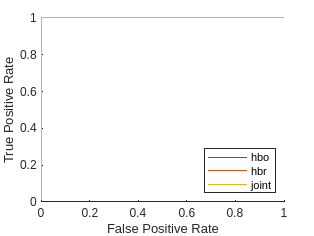

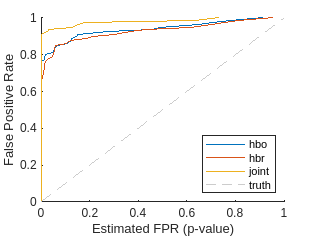

ROCtest(1).draw %draw     

ROCtest(1).auc  %auc  

ans =      1
     1
     1
